clf;clear;close all;clc

1.设置频率和传播速度，设置天线收发数量

Nt = 64;             % number of transmit antennas (BS)
Nr = 10;             % number of receiver antennas (UE)
fc = 24e9;
c = 3e8;
lamb = c/fc;

2.假设信道最多传输4路独立信号，DFRC编码矩阵是8阶，总功率为1

K = 8; 
L = 4;
P = 1;

3.以$\frac{\lambda }{2}$为间距设置天线阵列位置

spacing = lamb/2;
TxAntLoc = spacing*(0:Nt-1);
RxAntLoc = spacing*(0:Nr-1);

4.定义散射体和目标角度

%   AoDs (from BS to L scatterers)
AoD1 = [-30;0]; AoD2 = [-10;0]; AoD3 = [8;0]; AoD4 = [25;0];
%   AoAs (from L scatterers to UE)
AoA1 = [-30;0]; AoA2 = [-10;0]; AoA3 = [8;0]; AoA4 = [25;0];
%   Radar Target reflections
tgt1 = [-75;0]; tgt2 = [-45;0]; tgt3 = [52;0]; tgt4 = [80;0];
T = 50;
Kangles = zeros(2,K,T);
targets = zeros(2,L,T);
Langles = zeros(2,L,T);
LanglesUE = zeros(2,L,T);
for nt = 1:50
    Kangles(:,:,nt) = [tgt1, tgt2, AoD1, AoD2, AoD3, AoD4, tgt3, tgt4];
    targets(:,:,nt) = [tgt1, tgt2, tgt3, tgt4];
    Langles(:,:,nt) = [AoD1, AoD2, AoD3, AoD4];
    LanglesUE(:,:,nt) = [AoA1, AoA2, AoA3, AoA4];
    tgt1(1,1) = tgt1(1,1) + 0.2;
    tgt2(1,1) = tgt2(1,1) - 0.15;
    tgt3(1,1) = tgt3(1,1) + 0.2;
    tgt4(1,1) = tgt4(1,1) - 0.3;
end

5.计算转向矢量

% define steering vectors
TxArray = phased.ULA('NumElements',Nt, 'ElementSpacing', spacing);
TxSteerVec = phased.SteeringVector('SensorArray',TxArray);
RxArray = phased.ULA('NumElements',Nr, 'ElementSpacing', spacing);
RxSteerVec = phased.SteeringVector('SensorArray',RxArray);

% a(\theta) - all K targets
A_K = zeros(Nt,K,T); 
for nt = 1:T
    for k = 1:K
        A_K(:,k,nt) = TxSteerVec(fc,Kangles(:,k,nt));
    end
end

% a(\psi) - only AoDs
A_L = zeros(Nt,L,T); B_L = zeros(Nr,L,T);
for nt = 1:T
    for i = 1:L
        A_L(:,i,nt) = TxSteerVec(fc,Langles(:,i,nt));
        B_L(:,i,nt) = RxSteerVec(fc,LanglesUE(:,i,nt));
    end
end

% draw \beta_l from standard complex gaussian distribution (a+jb), a,b~N(0,1/2)
beta = sqrt(1/2)*(randn([L,1]) + 1i*randn([L,1]));
betaMat = diag(beta);

6.计算信道

extended Saleh-Valenzuela model：$$\mathbf{H}=\sum\limits_{l=1}^{L}{{{\beta }_{l}}\mathbf{b}\left( {{\phi }_{l}} \right){{\mathbf{a}}^{T}}\left( {{\varphi }_{l}} \right)}$$

% Create the channel matrix according to Eq. (5)
term = zeros(L,Nr,Nt);
H = zeros(Nr,Nt,T);
for nt = 1:T
    for i = 1:L
        term(i,:,:) = beta(i)*B_L(:,i,nt)*transpose(A_L(:,i,nt));
    end
    H(:,:,nt) = squeeze(sum(term));
end

7.计算估计信道


$$\tilde{\mathbf{H}} = diag(\beta)\mathbf{A}^T(\Theta_1)$$


% channel approximation \tilde{H} = diag(beta)A'(theta_1)
H_approx = zeros(L,Nt,T);
for nt = 1:T
    H_approx(:,:,nt) = betaMat*transpose(A_L(:,:,nt));
end

8.计算ZF波形


$$${{\mathbf{F}}_{BS}}={{\tilde{\mathbf{H}}}^{H}}{{\left( \mathbf{\tilde{H}}{{{\mathbf{\tilde{H}}}}^{H}} \right)}^{-1}}$$$



$$${{\mathbf{W}}_{UE}}={{\left( {{\mathbf{B}}^{H}}\left( \phi  \right)\mathbf{B}\left( \phi  \right) \right)}^{-1}}{{\mathbf{B}}^{H}}\left( \phi  \right)$$$


% create ZF beamformers Eq. (38)
F_bs = zeros(Nt,L,T);
W_ue = zeros(L,Nr,T);
for nt = 1:T
    F_bs(:,:,nt) = H_approx(:,:,nt)' * inv(H_approx(:,:,nt) * H_approx(:,:,nt)');
    W_ue(:,:,nt) = inv(B_L(:,:,nt)' * B_L(:,:,nt)) * B_L(:,:,nt)';
end

9.计算雷达波束


$$\[{{\mathbf{F}}_{RF}}\left( :,i \right)={{\mathbf{a}}^{*}}\left( {{\theta }_{i}} \right)\]$$


% Analog Beamformer F_rf Eq. (40)
F_rf = zeros(Nt,K,T);
for nt = 1:T
    for i = 1:K
        F_rf(:,i,nt) = conj(A_K(:,i,nt)); % conj:复共轭
    end
end

10.计算辅助矩阵


$$${ \tilde { \mathbf {H}}}{{\mathbf{F}}_{aux}}=0$$$


% Auxilary Matrix F_aux, where H_approx * F_aux = 0
F_aux_NSP = zeros(Nt,K-L,T);
for nt = 1:T
nullMat = null(H_approx(:,:,nt));
F_aux_NSP(:,:,nt) = nullMat(:,1:K-L);
end

11.计算通信矩阵


$$${{\mathbf{F}}_{BB}}=\sqrt{\frac{P}{K{{N}_{t}}}}\mathbf{\tilde{U}}{{\mathbf{\tilde{V}}}^{H}}$$$



$$$\mathbf{\tilde{U}\tilde{\Sigma }}{{\mathbf{\tilde{V}}}^{H}}=\mathbf{F}_{RF}^{H}\left[ {{\mathbf{F}}_{BS}},{{\mathbf{F}}_{aux}} \right]$$$


% Constructing the Digital Beamformer F_bb Eq. (42,43)
F_bb = zeros(K,K,T);
for nt = 1:T
svdMat = F_rf(:,:,nt)' * [F_bs(:,:,nt),F_aux_NSP(:,:,nt)];
[U,S,V] = svd(svdMat);
F_bb(:,:,nt) = sqrt(P/(K*Nt)) * U * V';
end

12.计算协方差矩阵


$$\[{{\mathbf{R}}_{s}}=\mathbb{E} \left( {{\mathbf{F}}_{D}}\mathbf{s}{{\mathbf{s}}^{H}}{{\mathbf{F}}_{D}} \right)={{\mathbf{F}}_{D}}\mathbb{E} \left( \mathbf{s}{{\mathbf{s}}^{H}} \right)\mathbf{F}_{D}^{H}={{\mathbf{F}}_{RF}}{{\mathbf{F}}_{BB}}\mathbf{F}_{BB}^{H}\mathbf{F}_{RF}^{H}\]$$



$$${{\mathbf{R}}_{ZF}}={{\mathbf{F}}_{BS}}\mathbf{F}_{BS}^{H}$$$


% Covariance Matrix Eq. (39)
R = zeros(Nt,Nt,T);
R_zf = zeros(Nt,Nt,T);
for nt = 1:T
    R(:,:,nt) = F_rf(:,:,nt) * F_bb(:,:,nt) * F_bb(:,:,nt)' * F_rf(:,:,nt)';    R(:,:,nt) = normalize(R(:,:,nt),'norm');
    R_zf(:,:,nt) = F_bs(:,:,nt) * F_bs(:,:,nt)';                R_zf(:,:,nt) = normalize(R_zf(:,:,nt),'norm');
end

13.绘制波束

transmit beampattern:

% Plot the beampatterns d(\theta) = transpose(a(\theta)) * R * conj(a(\theta))
% Find ALL steering vectors on [-pi,pi] to plot the beampattern 
angleSpace = linspace(-pi/2, pi/2, 360);
angleSpaceDeg = linspace(-90, 90, 360);
a = zeros(Nt, length(angleSpace));
for j = 1:Nt
    a(j,:) = exp((1i * 2 * pi * TxAntLoc(j) / lamb) .* sin(angleSpace));
end

dZF = zeros(length(angleSpace),T); d = zeros(length(angleSpace),T);
for nt = 1:T
    for i = 1:length(angleSpace)
        dZF(i,nt) = transpose(a(:,i)) * R_zf(:,:,nt) * conj(a(:,i));
        d(i,nt) = transpose(a(:,i)) * R(:,:,nt) * conj(a(:,i));
    end
end


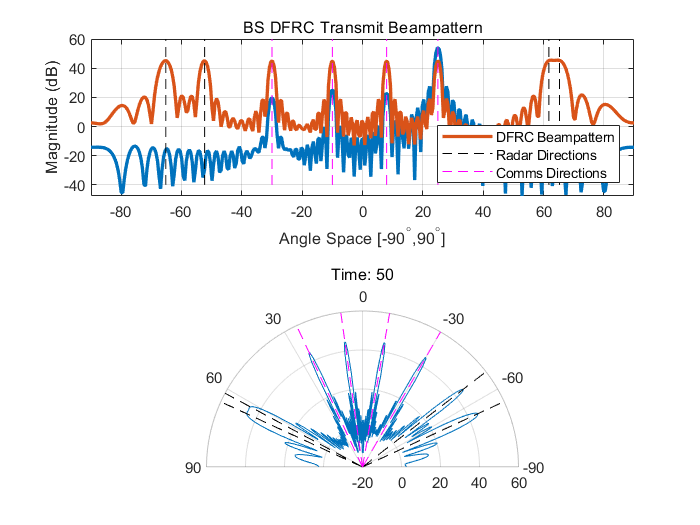

% PLOTTING BEAMPATTERNS -----------------------------------------------------
tgts_plot = targets(1,:,1);           % quick fix to deal with some annoying 
L_angles_plot = Langles(1,:,1);       % matrix dimensions
tiledlayout(2,1) 
nexttile
p(1) = plot(angleSpaceDeg, mag2db(abs(dZF(:,1))), 'LineWidth', 2);
hold on
for i = 1:length(tgts_plot)
    p(1+i) = line([tgts_plot(i) tgts_plot(i)], [-40 60], 'Color', 'black', 'LineStyle', '--');
    hold on
end
hold on
for i = 1:length(L_angles_plot)
    p(1+length(tgts_plot)+i) = line([L_angles_plot(i) L_angles_plot(i)], [-40 60], 'Color', 'magenta', 'LineStyle', '--');
    hold on
end
xlabel('Angle Space [-90^\circ,90^\circ]'); ylabel('Magnitude (dB)')
title('BS ZF Transmit Beampattern'); grid on; axis tight
% set(gcf,'color','w'); set(gcf, 'Position',  [50, 100, 1000, 400])
legend([p(1),p(1+length(tgts_plot)),p(1+length(tgts_plot)+length(L_angles_plot))],'ZF Beampattern','Radar Directions','Comms Directions', 'Location','southeast');
p(2+length(tgts_plot)+length(L_angles_plot)) = plot(angleSpaceDeg, mag2db(abs(d(:,1))), 'LineWidth', 2);
hold on
for i = 1:length(tgts_plot)
    p(2+length(tgts_plot)+length(L_angles_plot)+i) = line([tgts_plot(i) tgts_plot(i)],[-40 60], 'Color', 'black', 'LineStyle', '--');
    hold on
end
hold on
for i = 1:length(L_angles_plot)
    p(2+2*length(tgts_plot)+length(L_angles_plot)+i) = line([L_angles_plot(i) L_angles_plot(i)], [-40 60], 'Color', 'magenta', 'LineStyle', '--');
    hold on
end
xlabel('Angle Space [-90^\circ,90^\circ]'); ylabel('Magnitude (dB)')
title('BS DFRC Transmit Beampattern'); grid on; axis tight
% set(gcf,'color','w'); set(gcf, 'Position',  [50, 100, 1000, 400])
legend([p(2+length(tgts_plot)+length(L_angles_plot)),p(2+2*length(tgts_plot)+length(L_angles_plot)),p(2+2*length(tgts_plot)+2*length(L_angles_plot))],'DFRC Beampattern','Radar Directions','Comms Directions');
nexttile
p(3+2*length(tgts_plot)+2*length(L_angles_plot)) = polarplot(angleSpace, mag2db(abs(d(:,1))));
hold on
% polarplot(deg2rad([-75, -75]), [0,50], 'Color', 'black', 'LineStyle', '--');
thetalim([-90 90]);
rlim([-20 60]);
ax = gca;
ax.ThetaZeroLocation = 'top';
for i = 1:length(tgts_plot)
    p(3+2*length(tgts_plot)+2*length(L_angles_plot)+i) = polarplot(deg2rad([tgts_plot(i) tgts_plot(i)]), [-20,60], 'Color', 'black', 'LineStyle', '--');
    hold on
end
for i = 1:length(L_angles_plot)
    p(3+3*length(tgts_plot)+2*length(L_angles_plot)+i) = polarplot(deg2rad([L_angles_plot(i) L_angles_plot(i)]), [-20,60], 'Color', 'magenta', 'LineStyle', '--');
    hold on
end
ht = title("Time: 1");
for nt = 1:T
    set(p(1),XData=angleSpaceDeg,YData=mag2db(abs(dZF(:,nt))));
    for i = 1:length(tgts_plot)
        set(p(1+i),XData=[targets(1,i,nt) targets(1,i,nt)],YData=[-40 60]);
    end
    for i = 1:length(L_angles_plot)
        set(p(1+length(tgts_plot)+i),XData=[Langles(1,i,nt) Langles(1,i,nt)],YData=[-40 60]);
    end
    set(p(2+length(tgts_plot)+length(L_angles_plot)),XData=angleSpaceDeg,YData=mag2db(abs(d(:,nt))));
    for i = 1:length(tgts_plot)
        set(p(2+length(tgts_plot)+length(L_angles_plot)+i),XData=[targets(1,i,nt) targets(1,i,nt)],YData=[-40 60]);
    end
    for i = 1:length(L_angles_plot)
        set(p(2+2*length(tgts_plot)+length(L_angles_plot)+i),XData=[Langles(1,i,nt) Langles(1,i,nt)],YData=[-40 60]);
    end
    set(p(3+2*length(tgts_plot)+2*length(L_angles_plot)),XData=angleSpace,YData=mag2db(abs(d(:,nt))));
    for i = 1:length(tgts_plot)
        set(p(3+2*length(tgts_plot)+2*length(L_angles_plot)+i),XData=deg2rad([targets(1,i,nt) targets(1,i,nt)]),YData=[-20,60]);
    end
    for i = 1:length(L_angles_plot)
        set(p(3+3*length(tgts_plot)+2*length(L_angles_plot)+i),XData=deg2rad([Langles(1,i,nt) Langles(1,i,nt)]),YData=[-20,60]);
    end
    set(ht,String="Time: "+nt)
    pause(0.5);
    drawnow
    F=getframe(gcf);
    I=frame2im(F);
    [I,map]=rgb2ind(I,256);
    %     pathname = mfilename('fullpath');
    %     [pathname,~] = fileparts(pathname);
    %     pathname = strip(pathname);
    pathname = 'D:\OneDrive\Graduate\Code\MIMO-OFDM-Wireless-Communications-with-MATLAB\';
    if nt == 1
        imwrite(I,map,[pathname,'DFRC_Beamforming.gif'],'gif','Loopcount',inf,'DelayTime',0.2);

    else
        imwrite(I,map,[pathname,'DFRC_Beamforming.gif'],'gif','WriteMode','append','DelayTime',0.2);

    end
end